# Simple amplitude and delay manipulation

## Create a simple complex sinusoid waveform

Note: The shifting using complex exponentials works only if the signal is complex. Symbols in telecommunications are complex numbers, thus multiplication with a complex exponential leads to amplitude and phase changes.

t = 0:0.1:20; % seconds
fm = 0.05; % Hz
x = 2*cos(2*pi*fm*t) + 2*1i*sin(2*pi*fm*t);
plot(t,real(x), 'LineWidth',2);

Then we will apply the following:

- Amplitude increase by $\alpha =3\ldotp$

- Phase shift by $\phi =\frac{\pi }{2}\ldotp$

a = 1;
phi = -pi;
y = a*exp(1i*phi)*x;
hold on;
plot(t,real(y), 'LineWidth',1)

Let's combine the two signals and observe the output

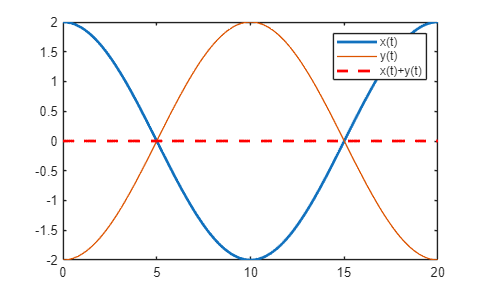

received_signal = x + y;
plot(t, real(received_signal), 'r--', 'LineWidth',2);
hold off;
legend('x(t)', 'y(t)', 'x(t)+y(t)');